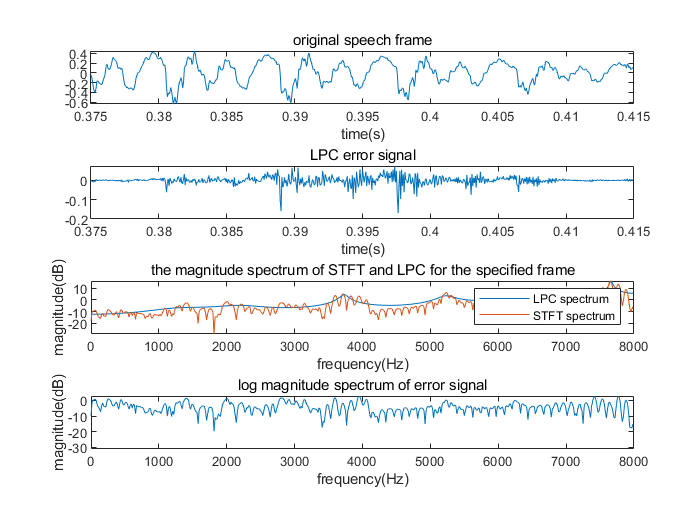

[s,fs]=audioread('test_16k.wav');
framesize=640;
starting_sample=6000;
LPC_order=12;

%extract frame hamming window
window=hamming(640);
frame=s(starting_sample:starting_sample+framesize-1)'.*window';
[a,error]=LPC(frame,LPC_order);

%using MATLAB function
A=lpc(frame,LPC_order);

%spectrum
Frame=fft(frame,1024);
Error=fft(error,1024);
Frame=10*log10(abs(Frame));
Error=10*log10(abs(Error));

%LPC spectrum
G=sqrt(sum(error.^2));
H=(G./(1-fft([0 a'],1024)));
H=10*log10(abs(H));

figure;
subplot(4,1,1);
t=s(starting_sample:starting_sample+framesize-1);
plot((starting_sample/fs):1/fs:((starting_sample+framesize-1)/fs),t');
title('original speech frame');
xlabel('time(s)');

subplot(4,1,2);
plot((starting_sample/fs):1/fs:((starting_sample+framesize-1)/fs),error);
title('LPC error signal');
xlabel('time(s)');

subplot(4,1,3)
plot(-fs/2:1/length(H)*fs:fs/2-1/length(H)*fs,H);
title('the magnitude spectrum of STFT and LPC for the specified frame');
hold on;
plot(-fs/2:1/length(Frame)*fs:fs/2-1/length(Frame)*fs,Frame);
xlabel('frequency(Hz)');
ylabel('magnitude(dB)');
legend('LPC spectrum','STFT spectrum');
axis([0,8000,min(Frame),max(Frame)]);

subplot(4,1,4);
plot(-fs/2:1/length(Error)*fs:fs/2-1/length(Error)*fs,Error);
title('log magnitude spectrum of error signal');
xlabel('frequency(Hz)');
ylabel('magnitude(dB)');
axis([0,8000,min(Error),max(Error)]);